# MODELOS EN VARIABLES DE ESTADOS

### SENALES Y SISTEMAS II

### EDUARDO TORO BERNAL

### INGENIERIA ELECTRONICA

### UNIVERSIDAD NACIONAL DE COLOMBIA

***CONSTRUCCION DE MODELOS EN VARIABLES DE ESTADO***

- Para crear un sistema modelado como una función de transferencia podemos usar: `Sys = tf (NUM, DEN, TS) `

***NUM:*** Vector que contiene los coeficientes del numerador de la función de transferencia, ordenados de la **mayor a la menor potencia**. 

***DEN: ***Vector que contiene los coeficientes del denominador de la función de transferencia, ordenados de la **mayor a la menor potencia**. 

***TS:*** Tiempo de muestreo para el caso de tiempo discreto. Si no se conoce dicho tiempo, colocamos -1. Para tiempo continuo no colocamos nada. 

Ejemplo 1:

Sys1 = tf ([10], [1 7 12])

Sys1 =
 
        10
  --------------
  s^2 + 7 s + 12
 
Continuous-time transfer function.



Ejemplo 2: 

Sys2 = tf([7 0], [1 0.2 -0.48], -1)

Sys2 =
 
         7 z
  ------------------
  z^2 + 0.2 z - 0.48
 
Sample time: unspecified
Discrete-time transfer function.



- Podemos definir un sistema partiendo de los polos, ceros y ganancia del mismo: **Sys = zpk (z, p, k, TS) **

**Z: **Vector de ceros del sistema. 

**P: **Vector de polos del sistema. 

**k: **Ganancia del sistema. 

**TS: **Periodo de muestreo. Aplican las mismas consideraciones anteriores. 

Ejemplo 1: 

Sys3 = zpk([], [-3 -4], 10)

Sys3 =
 
      10
  -----------
  (s+3) (s+4)
 
Continuous-time zero/pole/gain model.



Ejemplo 2: 

Sys4 = zpk([0], [0.6 -0.8], 7, -1)

Sys4 =
 
        7 z
  ---------------
  (z-0.6) (z+0.8)
 
Sample time: unspecified
Discrete-time zero/pole/gain model.



- Podemos crear un modelo en variables de estado a partir de la función de transferencia: **[A, B, C, D] = tf2ss (Num, Den)**

Ejemplo 1: 

[A, B, C, D] = tf2ss([10], [1 7 12])

A =     -7   -12
     1     0


B =      1
     0


C =      0    10


D = 0

¡IMPORTANTE! 

*Esta función solo esta definida para tiempo continuo. *

*Para tiempo discreto debemos tener el cuidado de expresar la función en potencias positivas de Z. *

Ejemplo 2: 

[A, B, C, D] = tf2ss([7 0], [1 0.2 -0.48])

A =    -0.2000    0.4800
    1.0000         0


B =      1
     0


C =      7     0


D = 0

- Podemos crear un sistema modelado como un modelo en variables de estado: **Sys = ss(A, B, C, D, TS) **

Ejemplo 1: 

Para la siguiente función de transferencia se obtuvo: 

A = [-3 0; 0 -4]

A =     -3     0
     0    -4


B = [10; 10]

B =     10
    10


C = [1 -1]

C =      1    -1


D = [0]

D = 0

Sys4 = ss(A,B,C,D)

Sys4 =
 
  A = 
       x1  x2
   x1  -3   0
   x2   0  -4
 
  B = 
       u1
   x1  10
   x2  10
 
  C = 
       x1  x2
   y1   1  -1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



**SOLUCION DE UN MODELO EN EL ESPACIO DE ESTADO**

- Se puede simular la **solución homogenea** a partir de las condiciones iniciales: [Y, T, X] = initial(Sys, x0, Tfinal, T)

**Sys:** Sistema que queremos simular, definido como un sistema en variables de estado. 

**X0:** Vector de condicones iniciales. 

**Tfinal:** (Opcional) Indica el fin de la simulación.

**T:** Como entrada es el vector de valores de tiempo en los que se desea la respuesta. 

**T:** Como salida es el vector de tiempo donde ocurren los valores indicados de Y y X. 

**X:** Vector de variables de estado en función del tiempo.

**Y:** Vector de señales de salida en función del tiempo. 

Ejemplo: 

%Encontrar las matrices de variables de estado. 
[A, B, C, D] = tf2ss([10], [1 7 12])

A =     -7   -12
     1     0


B =      1
     0


C =      0    10


D = 0

%Hallar modelado del sistema a partir de estas matrices. 
Sys5 = ss(A,B,C,D)

Sys5 =
 
  A = 
        x1   x2
   x1   -7  -12
   x2    1    0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   0  10
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%Aplicamos la simulación de solución homogenea con un
%vector de CI arbitrarias. 
[Y, T, X] = initial(Sys5, [1; 2])

Y =    20.0000
   20.1182
   20.1704
   20.1633
   20.1028
   19.9946
   19.8438
   19.6552
   19.4331
   19.1816


T =          0
    0.0154
    0.0307
    0.0461
    0.0614
    0.0768
    0.0921
    0.1075
    0.1228
    0.1382


X =     1.0000    2.0000
    0.5477    2.0118
    0.1399    2.0170
   -0.2266    2.0163
   -0.5552    2.0103
   -0.8489    1.9995
   -1.1103    1.9844
   -1.3422    1.9655
   -1.5468    1.9433
   -1.7264    1.9182


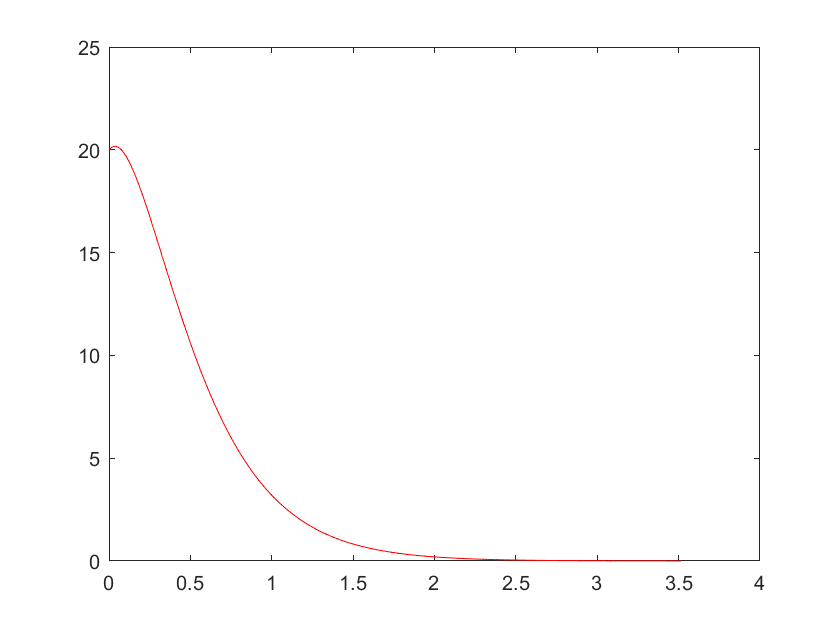

plot(T,Y, 'r')

- **Matriz de funciones de transferencia**  partir de un modelo en variables de estado: [Nun, Den] = ss2tf (A, B, C, D, iu) 

iu: Es el número de entradas del sistema, si hay más de una. 

A = [-2 -2; 1 -5]

A =     -2    -2
     1    -5


B = [2; 0]

B =      2
     0


C = [0 5]

C =      0     5


D = [0]

D = 0

[Num, Den] = ss2tf(A,B,C,D)

Num =      0     0    10


Den =      1     7    12


- Se puede simular la **solución particular **para **entradas escalón**: [Y, T, X] = step( Sys, Tfinal/T) 

**Sys:** Sistema que queremos simular. 

**Tfinal (opcional):** Indica el fin de la simulación.

**T (entrada):** Valores de tiempo en los que se desea la respuesta. 

**T (salida):** Valores de tiempo donde ocurren los valores indicados en X y Y. 

**X: **Vector de variables de estado en función del tiempo. 

**Y:** Vector de señales de salida en función del tiempo. 

2.  Se puede simular la **solución particular **para una **entrada arbitraria**: [Y, T, X] = lsim( Sys, U, T, X0).

**Sys:** Sistema que queremos simular.

**U: **Matriz de muestras de la señal de entrada.

**T:** Vector de valores de tiempo en los que ocurren los valores de U. 

**X0:** Vector de condiciones iniciales.